# Efficiency Map of Motor Drive Unit

## Basic thermal model

mdl = "MotorDriveUnit_refsub_BasicThermal";
MotorDriveUnit_refsub_BasicThermal_params
load_system(mdl)
blkpath = mdl + "/Motor Drive/Motor & Drive (Driveline)";
info = MotorDriveUnit_getBlockInfo_Basic(blkpath)

info = struct with fields:
                                 MaxTorque_Nm: 420
                                  MaxPower_kW: 220
                               ResponseTime_s: 0.0200
                               Efficiency_pct: 95
             SpeedAtEfficiencyMeasurement_rpm: 2000
             TorqueAtEfficiencyMeasurement_Nm: 50
    MechanicalPowerAtEfficiencyMeasurement_kW: 10.4720
         NominalLossAtEfficiencyMeasurement_W: 551.1566
            IronLossAtEfficiencyMeasurement_W: 55.1157
          CopperLossAtEfficiencyMeasurement_W: 496.0409


The "Basic Thermal" model uses Motor & Drive block from Simscape Driveline, the same block as the one the Basic model uses. The only difference is if the thermal model is enabled or not, and it does not affect the efficiency map.

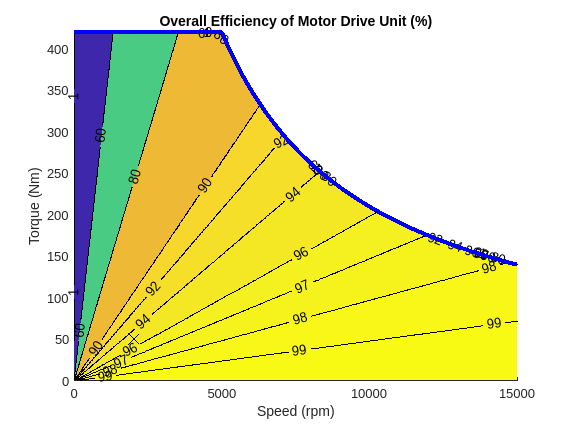

MotorDriveUnit_plotEfficiency_Basic( ...
  ... In road vehicle applications,
  ... maximum motor speed is determined by vehicle top speed,
  ... tire rolling radius, and reduction gear ratio. 
  MaxSpeed_rpm = 15000, ...
  ...
  MaxTorque_Nm = info.MaxTorque_Nm, ...
  MaxPower_kW = info.MaxPower_kW, ...
  Efficiency_pct = info.Efficiency_pct, ...
  SpeedAtEfficiencyMeasurement_rpm = info.SpeedAtEfficiencyMeasurement_rpm, ...
  TorqueAtEfficiencyMeasurement_Nm = info.TorqueAtEfficiencyMeasurement_Nm, ...
  ContourLevels_pct = [1 60 80 90 92 94 96 97 98 99], ...
  PlotResolution = 500 );

*Copyright 2021-2023 The MathWorks, Inc.*